## Metrics included with Warp Factory

Now that you understand the basics of metrics, here are some existing metrics to explore.

## Standard Metrics

### Minkowski

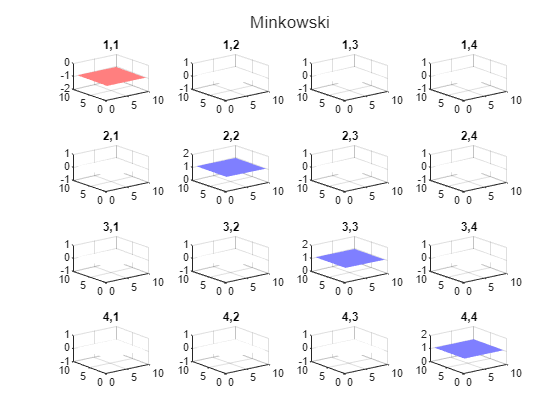

%% Minkowski
gridSize = [1 10 10 10];
gridScaling = [1 1 1 1];
Metric = metricGet_Minkowski(gridSize, gridScaling);

% Plotting
clf
for i = 1:4
    for j = 1:4
        h = nexttile;
        surfq(Metric.tensor{i,j}(1,:,:,1),'EdgeColor','none')
        title(num2str(i) + "," + num2str(j))
    end
end
sgtitle(Metric.name)

### Schwarzschild

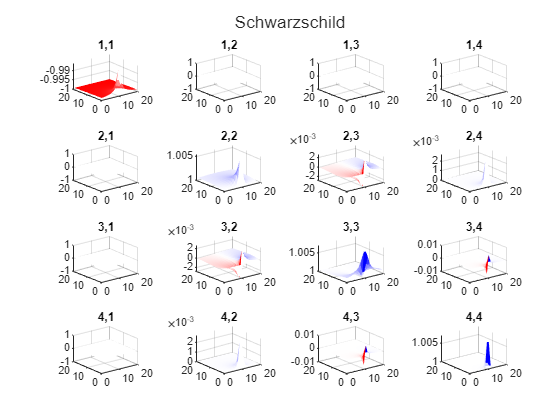

%% Schwarzschild
gridSize = [1 20 20 20];
worldCenter = (gridSize+1)./2;
rs = 0.01;
Metric = metricGet_Schwarzschild(gridSize,worldCenter,rs);

% Plotting
clf
for i = 1:4
    for j = 1:4
        h = nexttile;
        surfq(Metric.tensor{i,j}(1,:,:,round(worldCenter(4))),'EdgeColor','none')
        title(num2str(i) + "," + num2str(j))
    end
end
sgtitle(Metric.name)

## Warp Metrics - Time Dependent

These warp metrics move through the space. For a proper evaluation of the stress-energy tensor in warp factory, a minimum of 5 time steps must be instanced. Comoving metrics in the next section is preferred for most analyses since only 1 time slice is needed.

### Alcubierre - Time Dependent

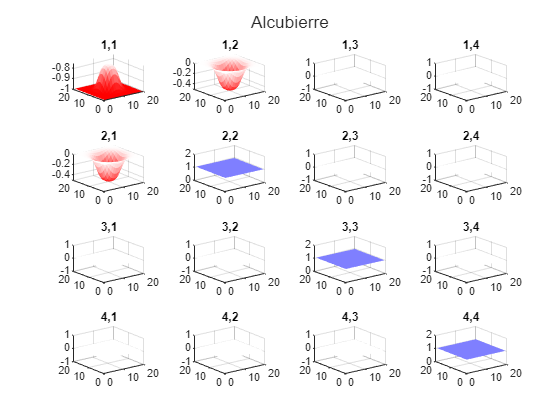

%% Alcubierre
gridSize = [5 20 20 20]; % Note the time size of 5
worldCenter = (gridSize+1)./2;
velocity = 0.5;
R = 5;
sigma = 0.5;
Metric = metricGet_Alcubierre(gridSize,worldCenter,velocity,R,sigma);

% Plotting
clf
for i = 1:4
    for j = 1:4
        h = nexttile;
        surfq(Metric.tensor{i,j}(3,:,:,round(worldCenter(4))),'EdgeColor','none')
        title(num2str(i) + "," + num2str(j))
    end
end
sgtitle(Metric.name)

### Van Den Broeck - Time Dependent

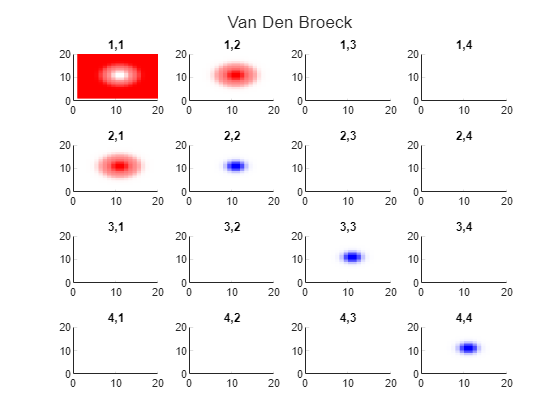

%% Van Den Broeck
gridSize = [5 20 20 20]; % Note the time size of 5
worldCenter = (gridSize+1)./2;
velocity = 0.1;
R1 = 2;
sigma1 = 1;
R2 = 5;
sigma2 = 1;
alpha = 0.5;
Metric = metricGet_VanDenBroeck(gridSize,worldCenter,velocity,R1,sigma1,R2,sigma2,alpha);

% Plotting
clf
for i = 1:4
    for j = 1:4
        h = nexttile;
        surfq(Metric.tensor{i,j}(3,:,:,round(worldCenter(4))),'EdgeColor','none')
        title(num2str(i) + "," + num2str(j))
        view(2)
    end
end
sgtitle(Metric.name)

### Lentz - Time Dependent

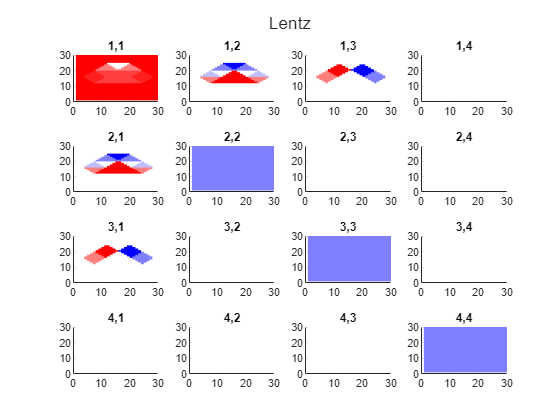

%% Lentz
gridSize = [5 30 30 2];  % Note the time size of 5, trailing size must be at least 2
worldCenter = (gridSize+1)./2;
velocity = 0.1;
Metric = metricGet_Lentz(gridSize,worldCenter,velocity);

% Plotting
clf
for i = 1:4
    for j = 1:4
        h = nexttile;
        surfq(Metric.tensor{i,j}(3,:,:,1),'EdgeColor','none')
        title(num2str(i) + "," + num2str(j))
        view(2)
    end
end
sgtitle(Metric.name)

## Warp Metrics - Comoving

These warp metrics do not move through the space, hence the name 'comoving'. For a proper evaluation of the stress-energy tensor in warp factory, only 1 time slice is needed since the metric is time-invariant.

### Alcubierre - Comoving

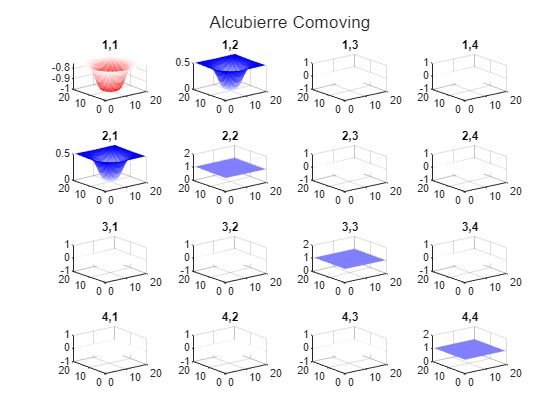

%% Alcubierre
gridSize = [1 20 20 20];
worldCenter = (gridSize+1)./2;
velocity = 0.5;
R = 5;
sigma = 0.5;
Metric = metricGet_AlcubierreComoving(gridSize,worldCenter,velocity,R,sigma);

% Plotting
clf
for i = 1:4
    for j = 1:4
        h = nexttile;
        surfq(Metric.tensor{i,j}(1,:,:,round(worldCenter(4))),'EdgeColor','none')
        title(num2str(i) + "," + num2str(j))
    end
end
sgtitle(Metric.name)

### Van Den Broeck - Comoving

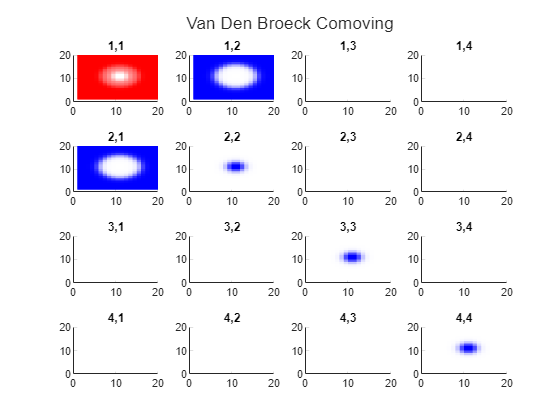

%% Van Den Broeck
gridSize = [1 20 20 20];
worldCenter = (gridSize+1)./2;
velocity = 0.1;
R1 = 2;
sigma1 = 1;
R2 = 5;
sigma2 = 1;
alpha = 0.5;
Metric = metricGet_VanDenBroeckComoving(gridSize,worldCenter,velocity,R1,sigma1,R2,sigma2,alpha);

% Plotting
clf
for i = 1:4
    for j = 1:4
        h = nexttile;
        surfq(Metric.tensor{i,j}(1,:,:,round(worldCenter(4))),'EdgeColor','none')
        title(num2str(i) + "," + num2str(j))
        view(2)
    end
end
sgtitle(Metric.name)

### Lentz - Comoving

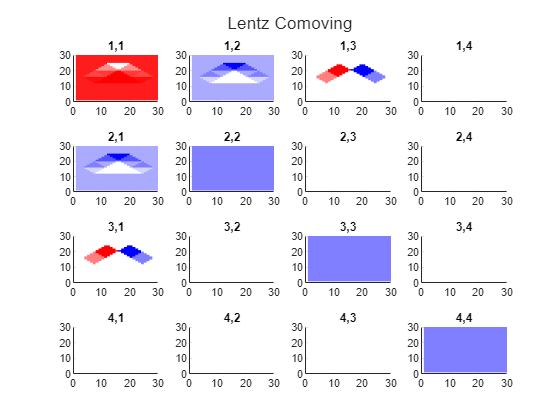

%% Lentz
gridSize = [1 30 30 2]; % Trailing size must be at least 2
worldCenter = (gridSize+1)./2;
velocity = 0.1;
Metric = metricGet_LentzComoving(gridSize,worldCenter,velocity);

% Plotting
clf
for i = 1:4
    for j = 1:4
        h = nexttile;
        surfq(Metric.tensor{i,j}(1,:,:,1),'EdgeColor','none')
        title(num2str(i) + "," + num2str(j))
        view(2)
    end
end
sgtitle(Metric.name)